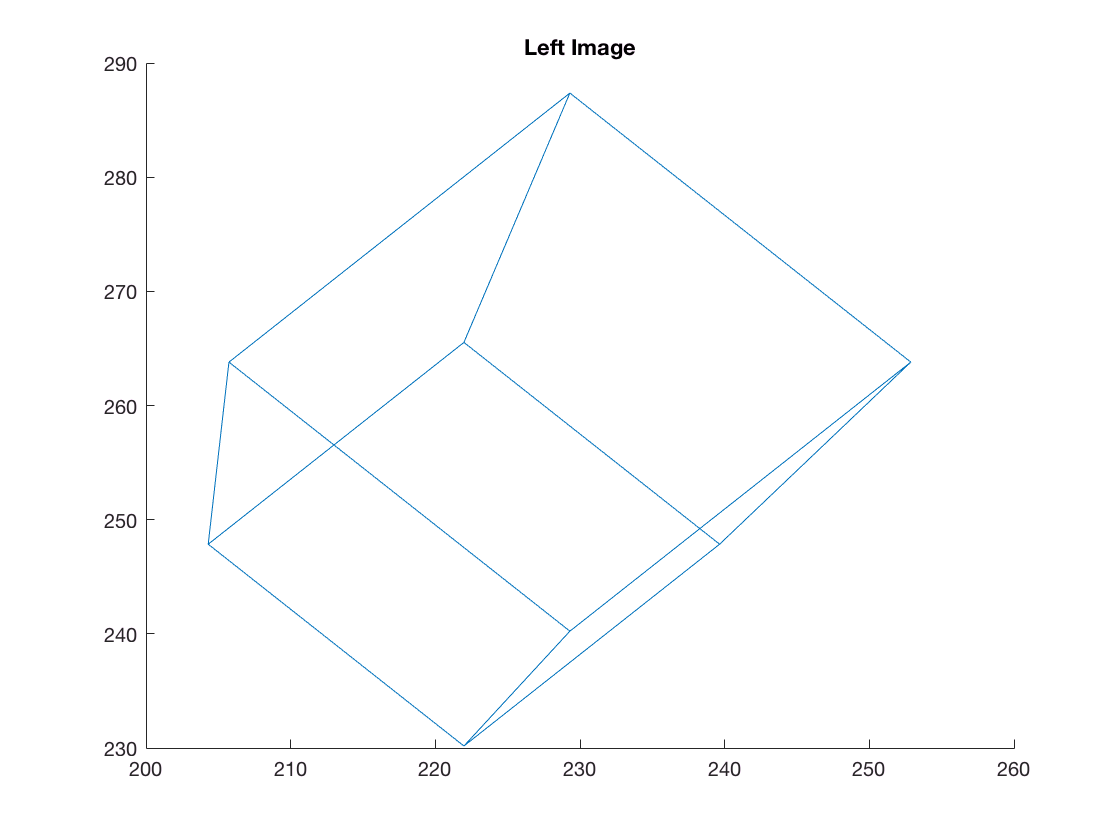

% Demonstration of 3D Reconstruction Using a Simple Polygonal Object
% intrinsic param
K = [-100 0 200 ;
    0 -100 200 ;
    0 0 1];

% extrinsic camera parameters
Mextleft = [ 0.707 0.707 0 -3 ;-0.707 0.707 0 -0.5; 0 0  1 3];
Mextright = [ 0.866 -0.5 0 -3 ;0.5 0.866 0 -0.5; 0 0 1 3];

pts = [ 2 0 0 ;
  3 0 0;
  3 1 0;
  2 1 0;
  2 0 1 ;
  3 0 1;
  3 1 1;
  2 1 1;
  2.5 0.5 2];
%for i = 1:9,
 %   pts(i,:) = rand(1,3);
%end;
     
%pts = [ 0 0 0 ; 0 1 0; 1 1 0; -1 1 0;1 0 1 ;1 0 1;1 1 1;1 1 1;1.5 0.5 2];

NN = 9;
pix = zeros(NN,3);
for i = 1:NN,
    pixels = K*Mextleft * [pts(i,1) pts(i,2) pts(i,3) 1]';
    leftpix(i,:) = pixels./pixels(3);
    pixels = K*Mextright * [pts(i,1) pts(i,2) pts(i,3) 1]';
    rightpix(i,:) = pixels./pixels(3);
end
    
% rightpix and leftpix are the list of corresponding points (attainable by
% ginput also

figure(1);clf;
drawmyobject(leftpix); title('Left Image');

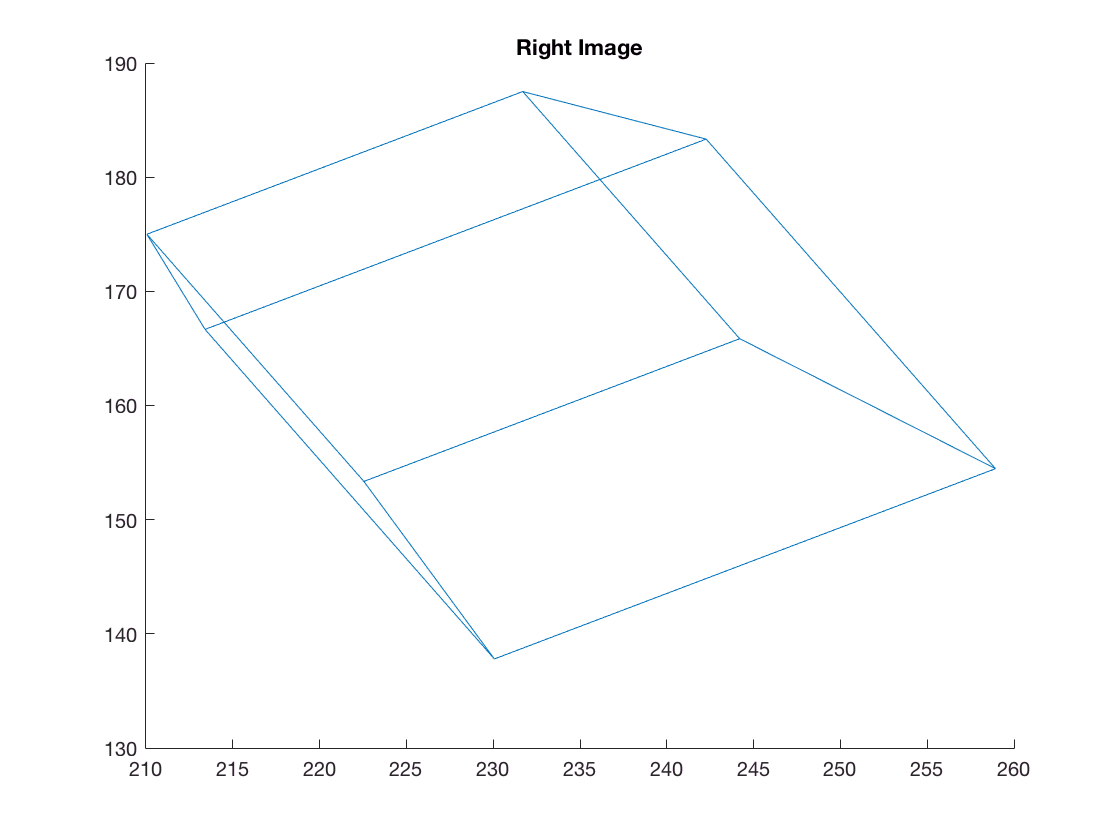

figure(2);clf;
drawmyobject(rightpix); title('Right Image');

## From pixels to rays

rightray = inv(K)*[rightpix(:,1) rightpix(:,2) rightpix(:,3)]';
leftray = inv(K)*[leftpix(:,1) leftpix(:,2) leftpix(:,3)]';

## STEREO RECONSTRUCTION With known camera matrices

Trw = [Mextright ; 0 0 0 1];
Tlw = [Mextleft; 0 0 0 1];
Twr = inv(Trw); % can be done using transpose
Twl = inv(Tlw); % can be done using transpose

Tlr = Tlw*Twr;
% Rotation from right to left coordinate frame 
Rlr = Tlr(1:3,1:3);
    % translation
tlr = Tlr(1:3,4);
reconpts = reconstruct3d(leftray,rightray,Rlr,tlr,Twl);

NN = 9

outpoint =    -1.5860
   -1.9140
    3.0000


outpoint =    -0.8790
   -2.6210
    3.0000


outpoint =    -0.1720
   -1.9140
    3.0000


outpoint =    -0.8790
   -1.2070
    3.0000


outpoint =    -1.5860
   -1.9140
    4.0000


outpoint =    -0.8790
   -2.6210
    4.0000


outpoint =    -0.1720
   -1.9140
    4.0000


outpoint =    -0.8790
   -1.2070
    4.0000


outpoint =    -0.8790
   -1.9140
    5.0000


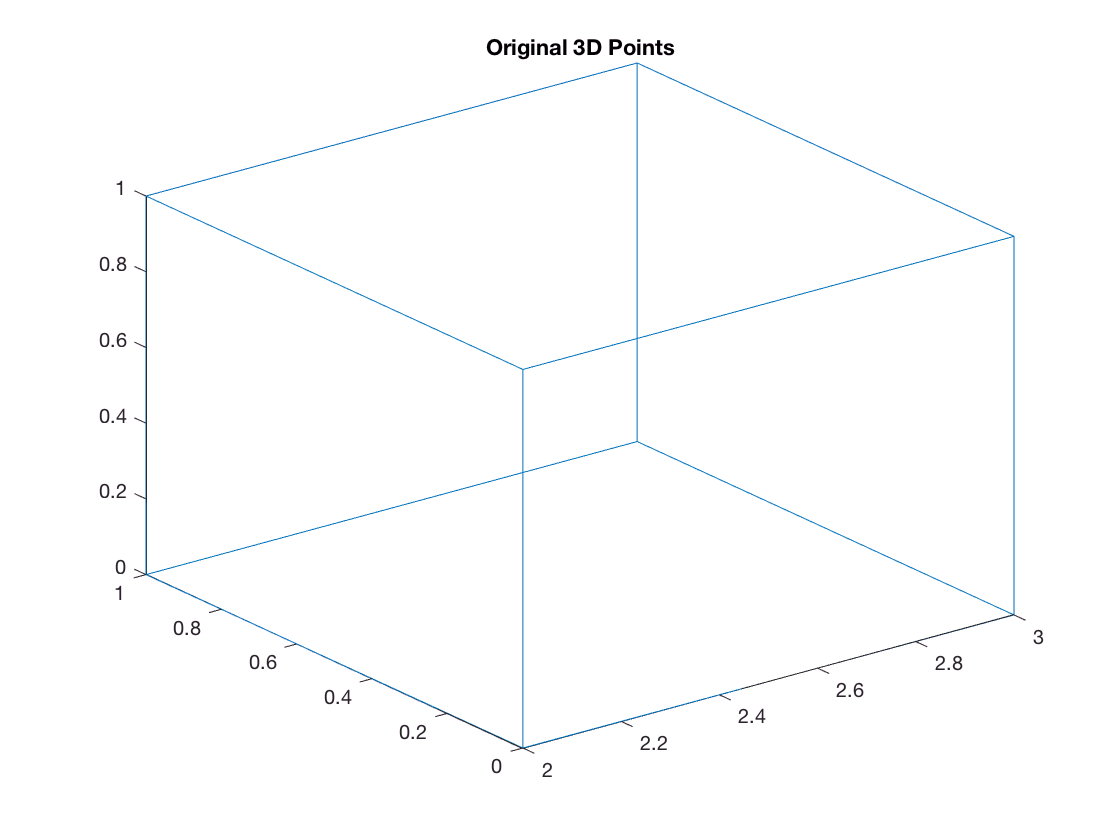


figure(3);clf;view(3)
drawmy3dobject(pts(:,1:3));title('Original 3D Points');

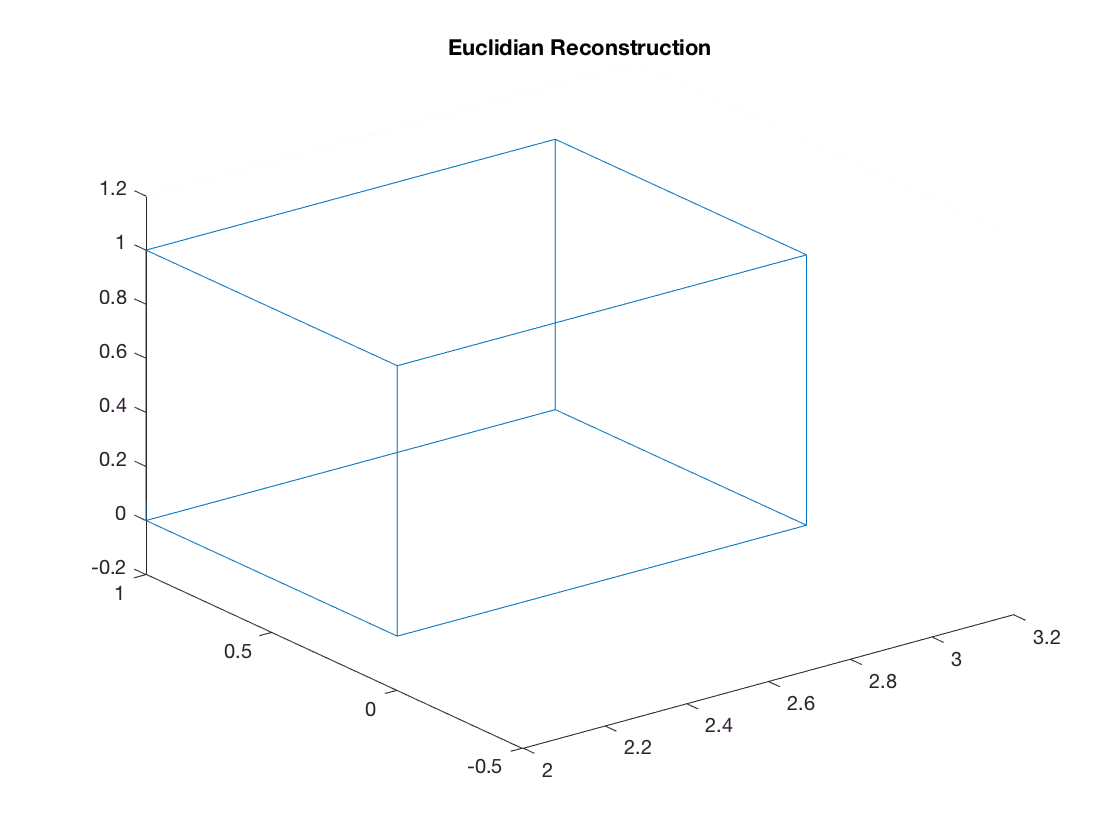


figure(4);clf;view(3)
drawmy3dobject(reconpts(:,1:3));title('Euclidian Reconstruction');



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% Now assume that no parameters are known and only point correspondences
% are given
% Reconstruct F from point correspondences.
% 
% Using the epipolar constraint between the point correspondences, F can be
% found


for i = 1:NN
tt=leftpix(i,:)' * rightpix(i,:) % 3 x3 matrix 
%form the matrix for Aq = 0, where q is 9x1 the elements of
A(i,:) = [tt(1,:) tt(2,:) tt(3,:)];
end;

tt =    1.0e+04 *

    6.1261    4.6359    0.0253
    6.3910    4.8363    0.0264
    0.0242    0.0183    0.0001


tt =    1.0e+04 *

    4.8933    3.8217    0.0229
    6.1324    4.7894    0.0287
    0.0213    0.0167    0.0001


tt =    1.0e+04 *

    4.7332    2.8350    0.0206
    6.0692    3.6352    0.0264
    0.0230    0.0138    0.0001


tt =    1.0e+04 *

    5.9373    3.5419    0.0229
    6.2204    3.7108    0.0240
    0.0259    0.0154    0.0001


tt =    1.0e+04 *

    5.5527    4.4934    0.0240
    5.7427    4.6472    0.0248
    0.0232    0.0187    0.0001


tt =    1.0e+04 *

    4.6626    3.8846    0.0222
    5.5774    4.6467    0.0266
    0.0210    0.0175    0.0001


tt =    1.0e+04 *

    4.5467    3.1329    0.0204
    5.5159    3.8008    0.0248
    0.0223    0.0153    0.0001


tt =    1.0e+04 *

    5.4206    3.6815    0.0222
    5.6209    3.8175    0.0230
    0.0244    0.0166    0.0001


tt =    1.0e+04 *

    4.8237    3.8368    0.0218
    5.2827    4.2018    0.0238
    0.0222    0.0176    0.0001


A

A =    1.0e+04 *

    6.1261    4.6359    0.0253    6.3910    4.8363    0.0264    0.0242    0.0183    0.0001
    4.8933    3.8217    0.0229    6.1324    4.7894    0.0287    0.0213    0.0167    0.0001
    4.7332    2.8350    0.0206    6.0692    3.6352    0.0264    0.0230    0.0138    0.0001
    5.9373    3.5419    0.0229    6.2204    3.7108    0.0240    0.0259    0.0154    0.0001
    5.5527    4.4934    0.0240    5.7427    4.6472    0.0248    0.0232    0.0187    0.0001
    4.6626    3.8846    0.0222    5.5774    4.6467    0.0266    0.0210    0.0175    0.0001
    4.5467    3.1329    0.0204    5.5159    3.8008    0.0248    0.0223    0.0153    0.0001
    5.4206    3.6815    0.0222    5.6209    3.8175    0.0230    0.0244    0.0166    0.0001
    4.8237    3.8368    0.0218    5.2827    4.2018    0.0238    0.0222    0.0176    0.0001



[U,S,V] = svd(A);
lastcol = V(:,9)

lastcol =    -0.0000
   -0.0000
    0.0044
    0.0000
    0.0000
   -0.0023
   -0.0034
   -0.0037
    1.0000


F(1,1) = lastcol(1); F(1,2) = lastcol(2); F(1,3) = lastcol(3);
F(2,1) = lastcol(4); F(2,2) = lastcol(5); F(2,3) = lastcol(6);
F(3,1) = lastcol(7); F(3,2) = lastcol(8); F(3,3) = lastcol(9);
F

F =    -0.0000   -0.0000    0.0044
    0.0000    0.0000   -0.0023
   -0.0034   -0.0037    1.0000



% Compare this to the built in call
%F = estimateFundamentalMatrix(rightpix(:,1:2),leftpix(:,1:2),'Method','Norm8Point');



% Get Camera Matrix From F
Ktemp = eye(3);
[U,S,V] = svd(F');
lastcol = V(:,3);
epipole = lastcol;
e1 = epipole(1);
e2 = epipole(2);
e3 = epipole(3);
ecross = [0 -e3 e2; e3 0 -e1; -e2 e1 0];
% camera matrix from F
cameramatrix = [ecross*F epipole];


% Reconstruct with triangulation
Rlr = cameramatrix(1:3,1:3);
tlr = cameramatrix(1:3,4); 

rightray_noK = [rightpix(:,1) rightpix(:,2) rightpix(:,3)]';
leftray_noK = [leftpix(:,1) leftpix(:,2) leftpix(:,3)]';
reconpts = reconstruct3d(leftray_noK,rightray_noK,Rlr,tlr,eye(4))

NN = 9

outpoint =    -0.7190
   -0.7501
   -0.0028


outpoint =    -0.6344
   -0.7951
   -0.0028


outpoint =    -0.6243
   -0.8005
   -0.0030


outpoint =    -0.7169
   -0.7511
   -0.0031


outpoint =    -0.7231
   -0.7478
   -0.0030


outpoint =    -0.6554
   -0.7839
   -0.0030


outpoint =    -0.6490
   -0.7873
   -0.0032


outpoint =    -0.7218
   -0.7485
   -0.0033


outpoint =    -0.6960
   -0.7623
   -0.0032


reconpts =    -0.7190   -0.7501   -0.0028    1.0000
   -0.6344   -0.7951   -0.0028    1.0000
   -0.6243   -0.8005   -0.0030    1.0000
   -0.7169   -0.7511   -0.0031    1.0000
   -0.7231   -0.7478   -0.0030    1.0000
   -0.6554   -0.7839   -0.0030    1.0000
   -0.6490   -0.7873   -0.0032    1.0000
   -0.7218   -0.7485   -0.0033    1.0000
   -0.6960   -0.7623   -0.0032    1.0000


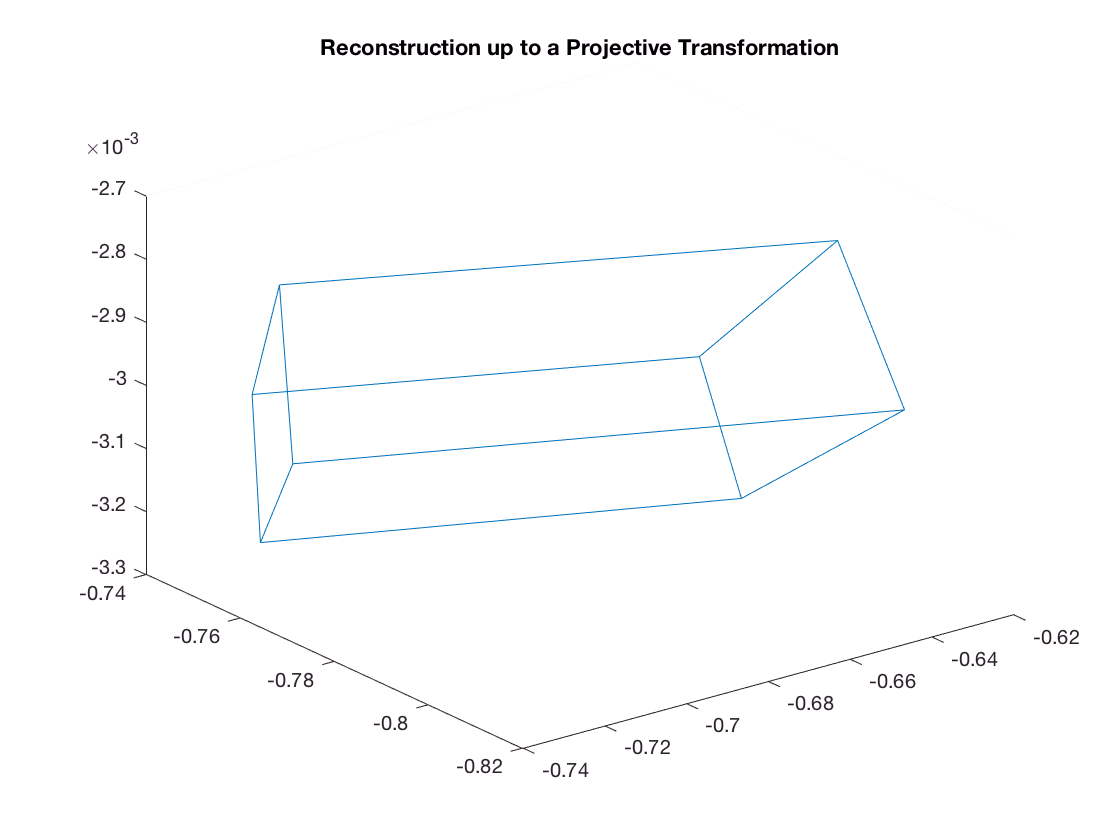

% Result is up to a projective transformation
figure(5);clf;view(3);
drawmy3dobject(reconpts(:,1:3));title('Reconstruction up to a Projective Transformation');

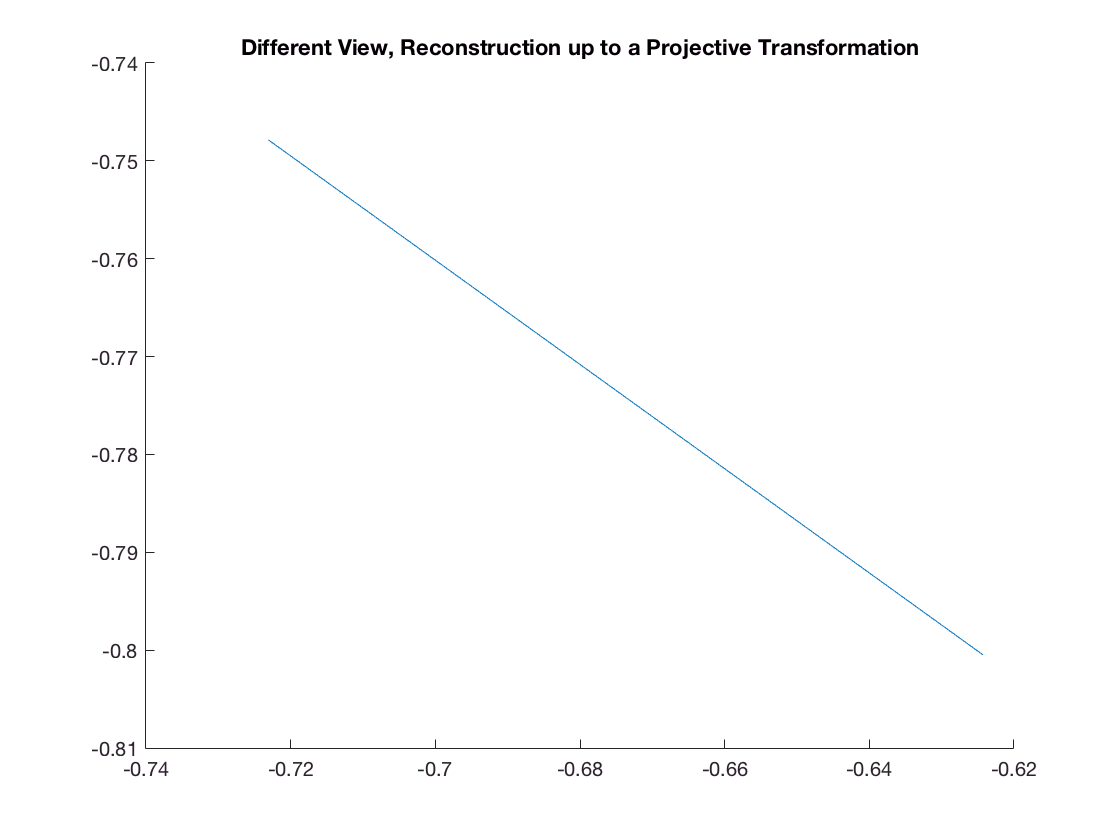

figure(6);clf;view(2);
drawmy3dobject(reconpts(:,1:3));title('Different View, Reconstruction up to a Projective Transformation');



%%%%%%%%% Find Essential Matrix
% Now assume you know K and find E.
E = K'*F*K;

% Get camera matrix from E , use standard method
W = [ 0 -1 0; 1 0 0 ; 0 0 1];
Z = [0 1 0; -1 0 0 ; 0 0 0];
[U,S,V] = svd(E); 
% four cases S1,R1 S2,R1  S1,R2  S2,R2
S1 = -U*Z*U';
S2 = U*Z*U';
R1 = U*W'*V';
R2 = U*W*V';

foundit = 0; % foundit flags that the +z reconstruction is found

%case 1
if (~foundit) 
    S = S1;R=R1;
    tlr= [ S(3,2) S(1,3) -S(1,2)]'
    reconpts = reconstruct3d(leftray,rightray,R,tlr,eye(4))
 if (min(reconpts(:,3))>0) foundit = 1;
    fprintf("Case 1");
    end
end

tlr =     0.4701
    0.8826
   -0.0000


NN = 9

outpoint =     1.3591
    1.6402
   -2.5708


outpoint =     0.5022
    1.4976
   -1.7141


outpoint =    -1.0571
  -11.7660
   18.4417


outpoint =    -1.1784
   -1.6181
    4.0217


outpoint =     1.3591
    1.6402
   -3.4278


outpoint =     0.5022
    1.4976
   -2.2855


outpoint =    -1.0570
  -11.7655
   24.5880


outpoint =    -1.1784
   -1.6181
    5.3623


outpoint =     1.7506
    3.8118
   -9.9578


reconpts =     1.3591    1.6402   -2.5708    1.0000
    0.5022    1.4976   -1.7141    1.0000
   -1.0571  -11.7660   18.4417    1.0000
   -1.1784   -1.6181    4.0217    1.0000
    1.3591    1.6402   -3.4278    1.0000
    0.5022    1.4976   -2.2855    1.0000
   -1.0570  -11.7655   24.5880    1.0000
   -1.1784   -1.6181    5.3623    1.0000
    1.7506    3.8118   -9.9578    1.0000



%case 2
if (~foundit) 
    S = S2;R=R1;
    tlr= [ S(3,2) S(1,3) -S(1,2)]';
    reconpts = reconstruct3d(leftray,rightray,R,tlr,eye(4))
    if (min(reconpts(:,3))>0) foundit = 1;
        fprintf("Case 2");
    end
end

NN = 9

outpoint =    -1.3591
   -1.6402
    2.5708


outpoint =    -0.5022
   -1.4976
    1.7141


outpoint =     1.0571
   11.7660
  -18.4417


outpoint =     1.1784
    1.6181
   -4.0217


outpoint =    -1.3591
   -1.6402
    3.4278


outpoint =    -0.5022
   -1.4976
    2.2855


outpoint =     1.0570
   11.7655
  -24.5880


outpoint =     1.1784
    1.6181
   -5.3623


outpoint =    -1.7506
   -3.8118
    9.9578


reconpts =    -1.3591   -1.6402    2.5708    1.0000
   -0.5022   -1.4976    1.7141    1.0000
    1.0571   11.7660  -18.4417    1.0000
    1.1784    1.6181   -4.0217    1.0000
   -1.3591   -1.6402    3.4278    1.0000
   -0.5022   -1.4976    2.2855    1.0000
    1.0570   11.7655  -24.5880    1.0000
    1.1784    1.6181   -5.3623    1.0000
   -1.7506   -3.8118    9.9578    1.0000




%case 3
if (~foundit) 
    S = S1;R=R2;
    tlr= [ S(3,2) S(1,3) -S(1,2)]';
    reconpts = reconstruct3d(leftray,rightray,R,tlr,eye(4))
    if (min(reconpts(:,3))>0) foundit = 1;
        fprintf("Case 3");
    end
end

NN = 9

outpoint =     0.4283
    0.5169
   -0.8102


outpoint =     0.2374
    0.7078
   -0.8102


outpoint =     0.0464
    0.5169
   -0.8102


outpoint =     0.2374
    0.3259
   -0.8101


outpoint =     0.4283
    0.5169
   -1.0802


outpoint =     0.2374
    0.7078
   -1.0802


outpoint =     0.0464
    0.5169
   -1.0802


outpoint =     0.2374
    0.3259
   -1.0802


outpoint =     0.2374
    0.5169
   -1.3503


reconpts =     0.4283    0.5169   -0.8102    1.0000
    0.2374    0.7078   -0.8102    1.0000
    0.0464    0.5169   -0.8102    1.0000
    0.2374    0.3259   -0.8101    1.0000
    0.4283    0.5169   -1.0802    1.0000
    0.2374    0.7078   -1.0802    1.0000
    0.0464    0.5169   -1.0802    1.0000
    0.2374    0.3259   -1.0802    1.0000
    0.2374    0.5169   -1.3503    1.0000




%case 4
if (~foundit) 
    S = S2;R=R2;
    tlr= [ S(3,2) S(1,3) -S(1,2)]';
    reconpts = reconstruct3d(leftray,rightray,R,tlr,eye(4))
   if (min(reconpts(:,3))>0) foundit = 1;
       fprintf("Case 4");
    end
end

NN = 9

outpoint =    -0.4283
   -0.5169
    0.8102


outpoint =    -0.2374
   -0.7078
    0.8102


outpoint =    -0.0464
   -0.5169
    0.8102


outpoint =    -0.2374
   -0.3259
    0.8101


outpoint =    -0.4283
   -0.5169
    1.0802


outpoint =    -0.2374
   -0.7078
    1.0802


outpoint =    -0.0464
   -0.5169
    1.0802


outpoint =    -0.2374
   -0.3259
    1.0802


outpoint =    -0.2374
   -0.5169
    1.3503


reconpts =    -0.4283   -0.5169    0.8102    1.0000
   -0.2374   -0.7078    0.8102    1.0000
   -0.0464   -0.5169    0.8102    1.0000
   -0.2374   -0.3259    0.8101    1.0000
   -0.4283   -0.5169    1.0802    1.0000
   -0.2374   -0.7078    1.0802    1.0000
   -0.0464   -0.5169    1.0802    1.0000
   -0.2374   -0.3259    1.0802    1.0000
   -0.2374   -0.5169    1.3503    1.0000


Case 4

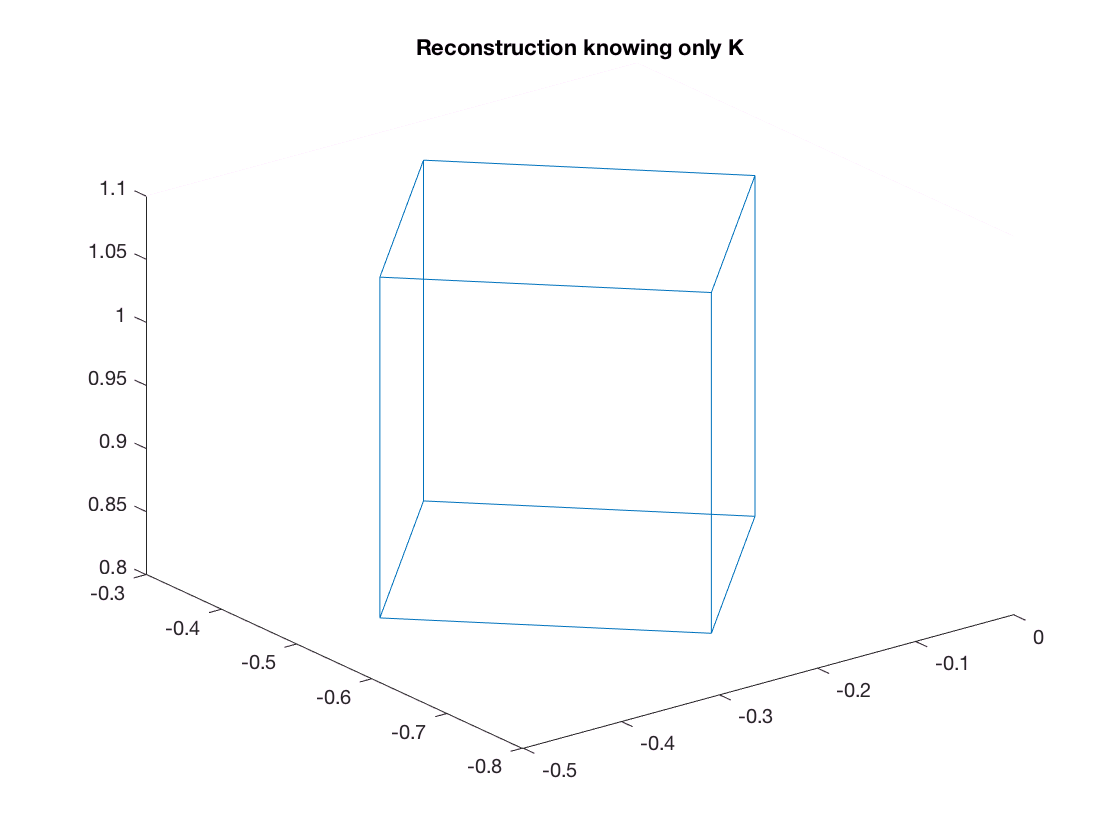



figure(7);clf;view(3);
drawmy3dobject(reconpts(:,1:3));title('Reconstruction knowing only K');